# NYU DBF Flight Performance Study

## Cruise Calculations

ref1 = '<a href = "https://www.google.com/url?sa=t&source=web&rct=j&opi=89978449&url=https://www.saeaerodesign.com/cdsweb/gen/DownloadDocument.aspx%3FDocumentID%3Dcd49237c-65b1-4744-9638-68903b7faf1d&ved=2ahUKEwiHvqzvl9iRAxUIM9AFHbKONrEQFnoECBsQAQ&usg=AOvVaw3mh-klgVQB4UXpSlohW7v8">RC Plane Drag Research</a>';
ref2 = '<a href = "https://aiaa.org/wp-content/uploads/2025/05/Top-3-Design-Reports.pdf">Top 3 Design Reports (2024-25)</a>';
ref3 = '<a href = "https://aiaa.org/wp-content/uploads/2025/05/Top-3-Proposals.pdf">Top 3 Proposals (2024-25)</a>';
ref4 = '<a href = "https://search.library.nyu.edu/discovery/fulldisplay?context=L&vid=01NYU_INST:NYU&search_scope=CI_NYU_CONSORTIA&tab=Unified_Slot&docid=alma990084330290107871">General Aviation Aircraft Design Textbook</a>';
ref5 = '<a href = "https://www.walshmedicalmedia.com/open-access/optimum-slat-and-flap-configuration-for-maximizing-lift-on-naca4412-airfoil-at-various-angle-of-attack-using-xfoil-at-a-.pdf">NACA-4412 Optimum Slat & Flap Paper</a>';
ref6 = '<a href = "https://koreascience.kr/article/JAKO200928842526583.pdf">NACA-4412 Flap CFD Study</a>';
ref7 = '<a href = "https://www.faa.gov/sites/faa.gov/files/regulations_policies/handbooks_manuals/aviation/airplane_handbook/14_afh_ch13.pdf">FAA Handbook</a>';
ref8 = '<a href = "https://www.airloads.net/Downloads/Textbooks/Theory%20of%20Wing%20Sections%20-%20Ira%20H.Abbott%20and%20Albert%20E.Von%20Doenhoff.pdf">Page 488 for NACA-4412</a>';
disp("References Used:")

References Used:


disp(ref1)

<a href = "https://www.google.com/url?sa=t&source=web&rct=j&opi=89978449&url=https://www.saeaerodesign.com/cdsweb/gen/DownloadDocument.aspx%3FDocumentID%3Dcd49237c-65b1-4744-9638-68903b7faf1d&ved=2ahUKEwiHvqzvl9iRAxUIM9AFHbKONrEQFnoECBsQAQ&usg=AOvVaw3mh-klgVQB4UXpSlohW7v8">RC Plane Drag Research</a>


disp(ref2)

<a href = "https://aiaa.org/wp-content/uploads/2025/05/Top-3-Design-Reports.pdf">Top 3 Design Reports (2024-25)</a>


disp(ref3)

<a href = "https://aiaa.org/wp-content/uploads/2025/05/Top-3-Proposals.pdf">Top 3 Proposals (2024-25)</a>


disp(ref4)

<a href = "https://search.library.nyu.edu/discovery/fulldisplay?context=L&vid=01NYU_INST:NYU&search_scope=CI_NYU_CONSORTIA&tab=Unified_Slot&docid=alma990084330290107871">General Aviation Aircraft Design Textbook</a>


disp(ref5)

<a href = "https://www.walshmedicalmedia.com/open-access/optimum-slat-and-flap-configuration-for-maximizing-lift-on-naca4412-airfoil-at-various-angle-of-attack-using-xfoil-at-a-.pdf">NACA-4412 Optimum Slat & Flap Paper</a>


disp(ref6)

<a href = "https://koreascience.kr/article/JAKO200928842526583.pdf">NACA-4412 Flap CFD Study</a>


disp(ref7)

<a href = "https://www.faa.gov/sites/faa.gov/files/regulations_policies/handbooks_manuals/aviation/airplane_handbook/14_afh_ch13.pdf">FAA Handbook</a>


disp(ref8)

<a href = "https://www.airloads.net/Downloads/Textbooks/Theory%20of%20Wing%20Sections%20-%20Ira%20H.Abbott%20and%20Albert%20E.Von%20Doenhoff.pdf">Page 488 for NACA-4412</a>



disp(" ")

disp("Preliminary Calculations to Determine Chord Dimension:")

Preliminary Calculations to Determine Chord Dimension:


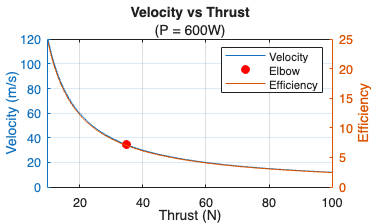

% Given E = 100 watt-hr 
% Code line 79 CD0 = 0.03 (ref2)
% energy = 100;
power = 100*3600/(60*5);
thrust = 1:200;
vel = power./thrust;
dv = gradient(vel);
d2v = gradient(dv);

% Elbow calculation using curvature k
k = d2v ./ (1 + (dv.^2)).^(3/2);
dk = gradient(k);
[~, idxElbow] = max(k);
thrElbow = thrust(idxElbow);
velElbow = vel(idxElbow);

% Efficiency calculations
w = 245;
eff = w./thrust;
effPlot(thrust,vel,eff,thrElbow,velElbow)

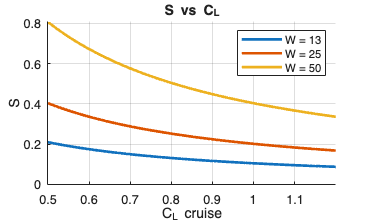


% S, c, AR, Re, & W/S calculations
rho = 1.225; %air density
mu = 1.8e-5; %air kinematic viscosity

Vcr = 30; % cruise velocity
Tcr = 20; % cruise thrust

bft = 5; % ft
bmet = bft * 0.3048; % m

W0 = 13; % Mission 1 & 3, 0 (lbf) payload weight (ref2)
Wpay = 25; % Mission 2, payload weight (lbf) (ref2)
Wmax = 50; % Max Weight (just to check)
Wlbf = [W0 Wpay Wmax]; % lbf
Wmet = Wlbf * 4.44822; % N

CLcr = linspace(0.5,1.2,100); % cruise lift coeff
q = 0.5 * rho * Vcr^2; % dynamic pressure

sz = [numel(Wmet), numel(CLcr)];
S  = ones(sz);
for idx = 1:numel(Wmet)
    S(idx,:) = Wmet(idx)./(q*CLcr);
end

c = S / bmet; % chord
AR = bmet^2 ./ S; % as
WS = q * CLcr; % WS = W/S = W/(W/(q*CLcr)) = q*CLcr
Re = rho * Vcr * c / mu; % reynolds number

graph(CLcr,S,Wlbf)

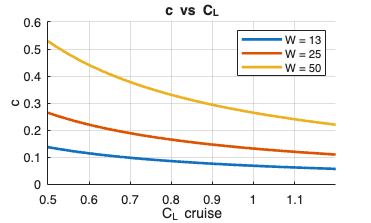

graph(CLcr,c,Wlbf)

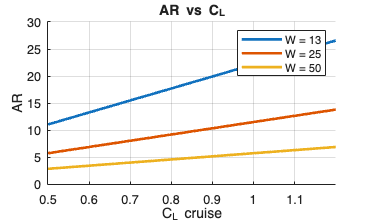

graph(CLcr,AR,Wlbf)

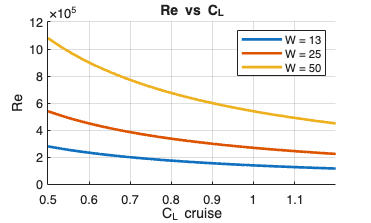

graph(CLcr,Re,Wlbf)

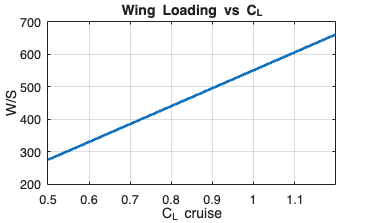


figure
plot(CLcr,WS,LineWidth=2)
xlabel("C_L cruise")
xlimArr = [CLcr(1),CLcr(end)];
xlim(xlimArr)
ylabel("W/S")
title("Wing Loading vs C_L")
grid on


cruiseTime = 1000 * 0.3048 / Vcr;
% Decided on NACA 4412 because
% Decided on CL Cruise of 1.1 which is 80% of the max CL of NACA 4412
% Decided on 10 inch for chord based on CL Cruise

## Take-Off Calculations

disp(" ")

disp("Take-Off Calculations:")

Take-Off Calculations:



c = 0.254; % closest inch (10 in)
S = c*bmet; % Wing Area
CLmaxLO = 2; % CL max with flaperon (ref6)

% Drag coeff. calculations
AR = bmet/c;
e = 0.95; % Oswald Efficiency
k = 1/(pi()*AR*e); 
CD0 = 0.03; % ref2
CD_LO = CD0 + k*CLmaxLO^2; % liftoff drag coeff
fric = 0.03; % wheel friction, asphalt free roll (ref4)

V_LO = ones(1, numel(Wmet));
takeoffDistance = ones(1, numel(Wmet));
for idx = 1:numel(Wmet)
    V_stall = sqrt((2*Wmet(idx))/(rho*S*CLmaxLO)); % stall velocity
    V_LO_idx = 1.2 * V_stall; % liftoff velocity 
    V_LO(idx) = V_LO_idx;

    q = 0.5*rho*V_LO_idx.^2; % dynamic pressure
    D = q*CD_LO*S; % drag force
    L = q*CLmaxLO*S; % lift force
    T_LO = power./V_LO_idx; % liftoff thrust

    distNum = V_LO_idx^2 * Wmet(idx);
    distDen = 2*9.81*(T_LO - D - fric*(Wmet(idx) - L));
    s = distNum/distDen; % ft
    if (s > 0) && (s < 500)
        disp(Wlbf(idx) + " (lbf) = " + s*3.28 + " ft @ " + V_LO_idx + " m/s Lift Off");
        takeoffDistance(idx) = s;
    else
        disp("Cannot Take Off at " + Wmet(idx)/4.44822 + " lbf")
        takeoffDistance(idx) = -1000;
    end
end

13 (lbf) = 21.0183 ft @ 13.2516 m/s Lift Off
25 (lbf) = 135.0707 ft @ 18.3767 m/s Lift Off


Cannot Take Off at 50 lbf


takeoffTime = 2.*takeoffDistance./V_LO;

## Climb Calculations

disp(" ")

disp("Climb Calculations:")

Climb Calculations:



climbVelRange = 10:35;
thrust = power./climbVelRange;

% drag calculations
CD_Climb = CD0 + k*CLmaxLO^2;
q = 0.5*rho*climbVelRange.^2;
drag = q.*CD_Climb*S;

Texc = thrust - drag; % excess thrust [N]
[TexMax, i] = max(Texc); % maximize (T-D) for Vx
Vx = climbVelRange(i);

height = 300 * 0.3048;
ROC_arr = ones(1, numel(Wmet));
tClimb_arr = ones(1, numel(Wmet));
for idx = 1:numel(Wmet)
    s = max(min(TexMax/Wmet(idx), 1), -1);
    gamma = asin(s); % climb angle [rad]
    gamma_deg = gamma * 180/pi; % climb angle [deg]
    ROC = climbVelRange .* s; % [m/s]  (since ROC = V*sin(gamma))
    Vh  = climbVelRange .* cos(gamma); % [m/s]

    % Vy: maximize rate of climb (or equivalently maximize V*(T-D))
    [ROCmax, iVy] = max(ROC);
    Vy = climbVelRange(iVy);
    gammaVy = gamma; 
    VhVy = Vh(iVy);
    
    ROC_arr(idx) = ROCmax;
    tClimb = height / ROCmax;
    tClimb_arr(idx) = tClimb;
    x = VhVy * tClimb / 0.3048;
    disp(Wlbf(idx) + " (lbf) = " + ROCmax + " m/s RoC @ " + tClimb + " s to Altitude")
end

13 (lbf) = 35 m/s RoC @ 2.6126 s to Altitude
25 (lbf) = 35 m/s RoC @ 2.6126 s to Altitude
50 (lbf) = 17.9386 m/s RoC @ 5.0974 s to Altitude


## Turn Calculations

disp(" ")

disp("Turn Calculations:")

Turn Calculations:



Vcr = 30; % m/s
CD_Turn = CD0 + k*CLmaxLO^2;
q = 0.5*rho*Vcr^2;
drag = q*CD_Turn*S;
thrust = power/Vcr;
lift = q*CLmaxLO*S;

% Using excess lift, calculated LcosTheta - W = 0
bankAngle = acos(Wmet./lift);
bankAngleDeg = acosd(Wmet./lift);
loadFactor = 1./cos(bankAngle);
% Override Load Factors > 1
for idx = 1:numel(Wmet)
    if loadFactor(idx) > 5
        loadFactor(idx) = 5;
        bankAngle(idx) = acos(1/5);
        bankAngleDeg(idx) = acosd(1/5);
    end
end

turnRadius = Vcr^2 ./ (9.81.*sqrt(loadFactor.^2 - 1));
turnTime = turnRadius./Vcr * pi();

for idx = 1:numel(Wmet)
    disp("~ ~ ~ ~ ~")
    disp(Wlbf(idx) + " (lbf):")
    disp("Bank Angle: " + bankAngleDeg(idx) + " deg")
    disp("Load Factor: " + loadFactor(idx) + " G's")
    disp("Turn Radius: " + turnRadius(idx)/0.3048 + " ft")
    disp("Turn Time: " + turnTime(idx) + " s")
end

~ ~ ~ ~ ~


13 (lbf):


Bank Angle: 78.463 deg


Load Factor: 5 G's


Turn Radius: 61.4402 ft


Turn Time: 1.9611 s


~ ~ ~ ~ ~


25 (lbf):


Bank Angle: 74.896 deg


Load Factor: 3.8377 G's


Turn Radius: 81.2374 ft


Turn Time: 2.593 s


~ ~ ~ ~ ~


50 (lbf):


Bank Angle: 58.5909 deg


Load Factor: 1.9188 G's


Turn Radius: 183.7936 ft


Turn Time: 5.8664 s


## Lap Time

disp(" ")

disp("1 Lap Times:")

1 Lap Times:


totalTime = cruiseTime + 4 * turnTime + 2*tClimb_arr + 2*takeoffTime;
for idx = 1:numel(Wmet)
    disp(Wlbf(idx) + " (lbf): " + totalTime(idx) + " s")
end

13 (lbf): 25.1637 s
25 (lbf): 34.7206 s
50 (lbf): -110.0935 s


## Touchdown Calculations

disp(" ")

disp("Touchdown Calculations:")

Touchdown Calculations:



% using same parameters as takeoff calculations (rho, e, fric, etc)
h = 0.5; % Airfoil height off the ground (ft)
g = 9.81; % m/s
hmet = h * 0.3048; % m
hb_ratio = hmet / bmet; % h = height of wing from ground; b = wingspan

ClmaxTD = 1.5; % Ref8, over airfoil (Abbott)
AOA_TDSTALL = 13; % deg
CLmaxTD_OGE = 0.9 * ClmaxTD; % over wing

% MUST BE ADJUSTED FOR DIFFERENT h/b RATIO, at h/b = 0.1, correction ~ 1.08 (Hoerner)
CLmaxTD = CLmaxTD_OGE * 1.08; % corrected CLmax at touchdown

S = c*bmet; % wing area
CD_Air_Breaks = 0.1 + k*(CLmaxTD)^2;
CD_TD = CD0 + k*(CLmaxTD)^2 + CD_Air_Breaks;

for idx = 1:numel(Wmet)
    V_StallTD = sqrt((2*Wmet(idx))/(rho*S*CLmaxTD));
    V_TD = 1.2 * V_StallTD;
    V_app = 1.3 * V_StallTD;
    
    V_ground = linspace(V_TD, 0, 150); %from touchdown to stop
    
    %0.5*rho * V_ground.^2 := dynamic pressure at touch down
    D_TD = 0.5 * rho * V_ground.^2 *CD_TD*S; % drag force at touchdown
    L_TD = 0.5 * rho * V_ground.^2 *CLmaxTD*S; % lift force at touchdown
    
    %Need deceleraion & total ground roll in code section
    fric = 0.03; %asphalt
    
    T_TD = 0; %MISSING THRUST VALUE DURING LANDING; NEED TO MODIFY INST. AC.
    a_ground = (g/Wmet(idx)) .* (T_TD - D_TD - fric*(Wmet(idx) - L_TD)); %textbook (23-1)
    
    Sg = trapz(V_ground, V_ground ./ a_ground); % trapezoidal integration
    disp(Wlbf(idx) + " (lbf): " + Sg/0.3048 + " ft till stop")
end

13 (lbf): 309.4263 ft till stop
25 (lbf): 595.0505 ft till stop
50 (lbf): 1190.101 ft till stop


% ~~~~~~~~ Functions ~~~~~~~~ %
function effPlot(thrust,velocity,efficiency,thrPoint,velPoint)
    yyaxis left
    plot(thrust,velocity)
    xlim([10 100])
    xlabel("Thrust (N)")
    ylabel("Velocity (m/s)")
    title("Velocity vs Thrust", "(P = 600W)")
    grid on
    hold on
    plot(thrPoint,velPoint,"r.",MarkerSize=20)
    yyaxis right
    plot(thrust,efficiency)
    ylabel("Efficiency")
    legend("Velocity", "Elbow", "Efficiency")
    hold off
end

function graph(X,Y,legendMat)
    [col,~] = size(Y);
    figure
    hold on
    for idx = 1:col
        plot(X, Y(idx,:), LineWidth=2)
    end
    hold off
    grid on
    legendStr = "W = " + legendMat;
    legend(legendStr)
    xlabel("C_L cruise")
    xlim([X(1) X(end)])
    Ystr = inputname(2);
    ylabel(Ystr)
    titleStr = Ystr + " vs C_L";
    title(titleStr)
end